% Constants
mu0 = 4e-7*pi;

% Variables
rad_in = 0.85; % inner loop radius
A_in = pi*rad_in^2;
rad_out = 1.5; % outter loop radius
A_out = pi*rad_out^2;
R = 8; % material resistance

v_init = 1; % initial voltage

t_init = 0;
t_final = 100;
dt = 0.05;
t = t_init:dt:t_final;

% derivative of voltage over time
k = (2 * R * rad_in * rad_out)/(mu0 * pi * rad_in^2) * 1e-6;

% Define v_prime using a nested function or a conditional check
v_prime = @(t_val, v_val) calculate_v_prime(t_val, k);

function dvdt = calculate_v_prime(t_val, k_const)
    if t_val == 0
        dvdt = k_const * 1; % Limit of sin(t)/t as t->0 is 1
    else
        dvdt = k_const * (sin(t_val) / t_val);
    end
end

% This ODE models the voltage decay due to magnetic braking (eddy currents).
% It was derived from Faraday's Law: emf = -dΦ/dt, with magnetic flux Φ proportional to B*A.
% Using Biot–Savart law, we approximated B as a function of time: B(t) ∝ sin(t)/t.
% Then, applying Ohms’s law (V = iR) and considering V = emf, we obtained:
% dv/dt = k * (sin(t)/t), where k groups the physical constants of the system.

% voltage vector
v = zeros(1, length(t));
v(1) = v_init;

% apply euler's method
v(1) = v_init;
for i = 1:length(t)-1
    v(i+1) = v(i) + v_prime(t(i), v(i)) * dt;
end

% apply midpoint method
v_mid = RK2(v_prime, t_init, t_final, v_init, dt, 1);

% apply Heun method
v_heun = RK2(v_prime, t_init, t_final, v_init, dt, 1/2);

% apply Ralston method
v_ralston = RK2(v_prime, t_init, t_final, v_init, dt, 2/3);

% apply RK4 
v_rk4 = RK4(v_prime, t_init, t_final, v_init, dt);

fprintf("Euler: Current at time = 100: %.2f A", v(length(v))/R);

Euler: Current at time = 100: 1.54 A

fprintf("Midpoint: Current at time = 100: %.2f A", v_mid(length(v))/R);

Midpoint: Current at time = 100: 1.52 A

fprintf("Heun: Current at time = 100: %.2f A", v_heun(length(v))/R);

Heun: Current at time = 100: 1.52 A

fprintf("Ralston: Current at time = 100: %.2f A", v_ralston(length(v))/R);

Ralston: Current at time = 100: 1.52 A

fprintf("RK4: Current at time = 100: %.2f A", v_rk4(length(v))/R);

RK4: Current at time = 100: 1.52 A

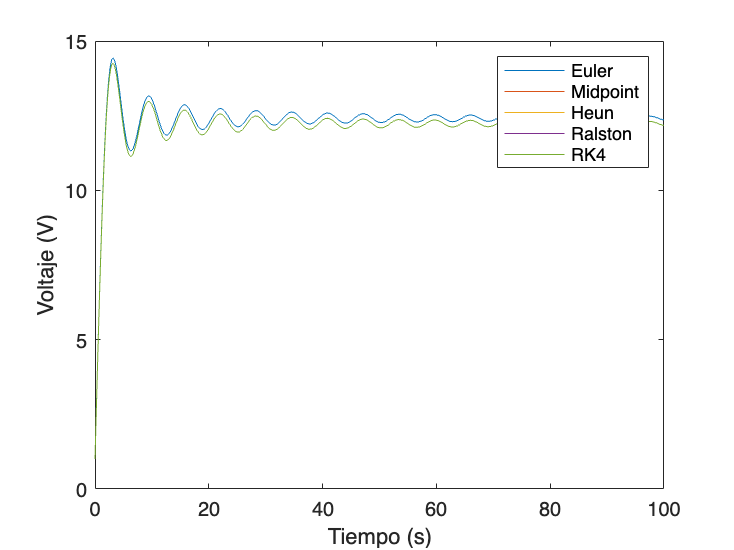


plot(t, v); hold on;
plot(t, v_mid);
plot(t, v_heun);
plot(t, v_ralston);
plot(t, v_rk4);
legend('Euler','Midpoint','Heun','Ralston','RK4');
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');